# Business Statistics and Data Analytics

## Overview of Data Analytics

Data analytics turns a business records into decisions. It is a pipeline, not a single calculation. Each stage changes the table the next stage sees.

A conclusion can never be better than the table it was computed from, which is why cleaning takes up most of this script.

## Workflow of Data Analytics

- **Import** — read the file and declare what each column means

- **Assess** — measure what is wrong before changing anything

- **Clean** — duplicates, inconsistent text, missing values, outliers

- **Explore** — chart the data to answer business questions

- **Conclude** — state what to act on

## Task 1: Import the Raw Data

Open "Import Data" task in "LIVE EDITOR" tab

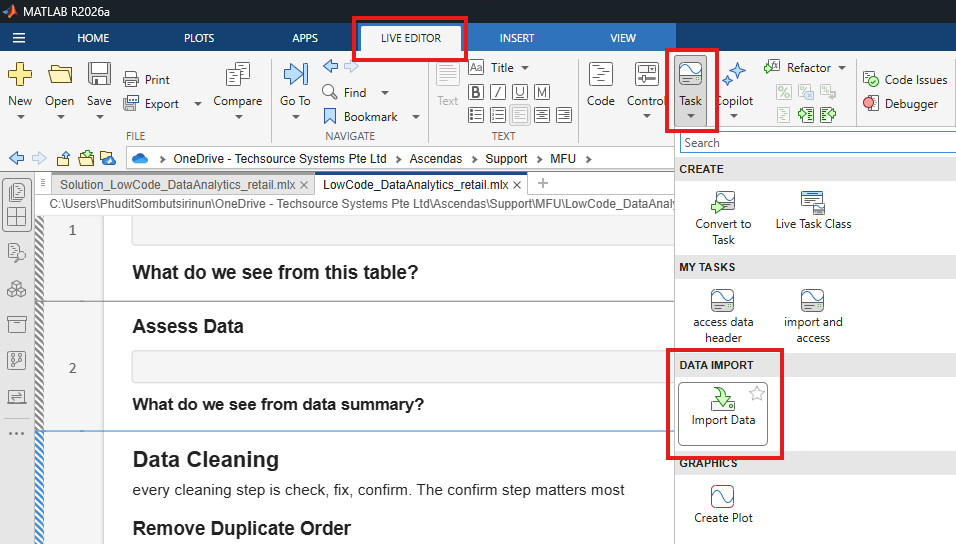

Click "Browse" and open `online_retail_demo`

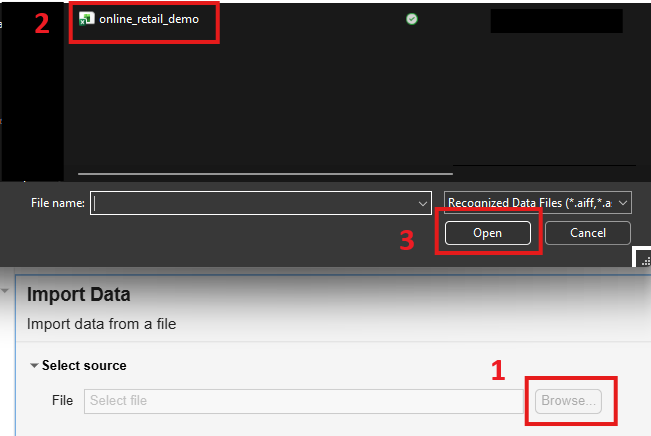

### What do we see from this table?

### 1.1: Assess Data

#### What do we see from data summary?

## Task 2: Data Cleaning

Every cleaning step is check, fix, confirm. The confirm step matters most

### 2.1: Remove Duplicate Order

1 order ID means 1 sale. A repeated ID counts the same sale twice and inflates every total that follows.

**Check**

Compare the number of unique order IDs with the number of rows; the gap is the number of duplicates.

*Recommendation***:** create another variable to process the data without alternating the raw data

**Remove  & Confirm**

`unique` with `"stable"` returns the first appearance of each ID and keeps the rows in their original order.

### 2.2: Clean Text

Labels that mean the same thing must be spelled the same way before they can be counted. Text cleaning in MATLAB always follows one shape — tokenize, transform, rejoin.

**Change the variable type for preprocessing** 

#### 2.2.1: Clean ProductType

From the data, we can see that `ProductType `is polluted by an article like "a", "the", "This", etc. that prevent the effectiveness of data analysis. 

**Check unique entry**

**Select "Preprocess Text Data" task**

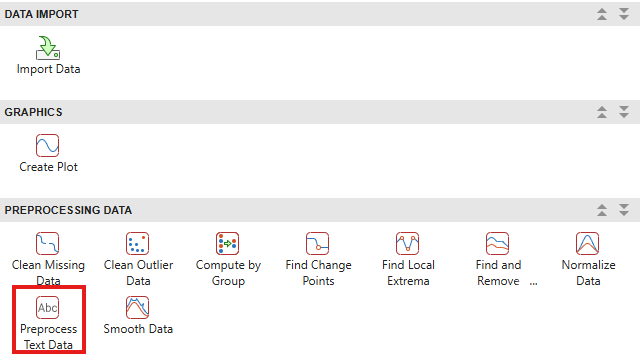

**Select the preprocess option**

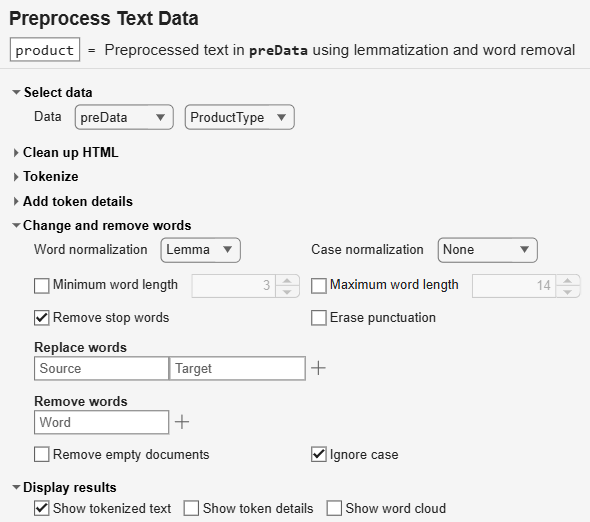

**Convert the tokenized text to string and check unique entry**

**Change the variable type to categorical for later analysis**

#### 2.2.2: Clean Brand

From the data, we can see that Brand has a punctuation that lead to the incorrect counting

**Check unique entry**

**Open "Preprocess Text Data" task and select the preprocess option**

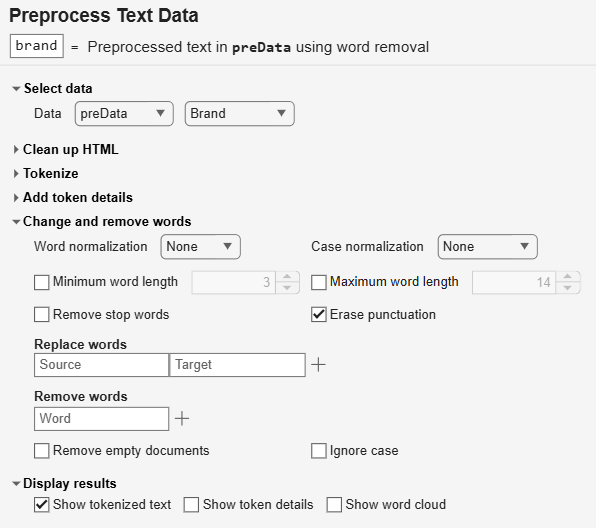

**Convert the tokenized text to string and check unique entry**

**Change the variable type to categorical for later analysis**

### 2.3: Fill Missing Values

There are 2 columns that have missing values `Brand and UnitPrice. `Before filling any missing value, we have to

- Detect the missing value

- Diagnose the data - Is there a pattern?

- Pick the strategy

- Delete

- Fill with mean/median/mode or constant

- Group-based 

#### 2.3.1: Fill missing Brand

Detect the index of missing value by

**Diagnose the missing Brand by open "Pivot Table"**

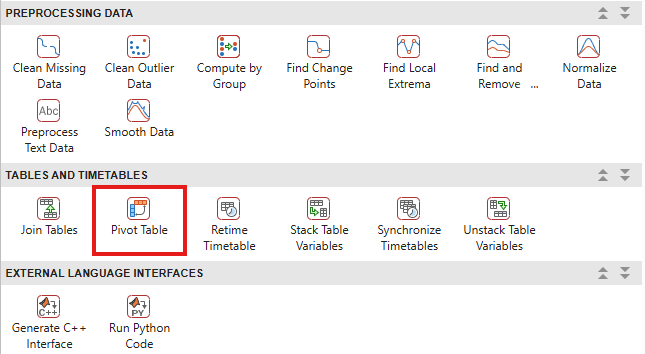

**Select pivot variables **

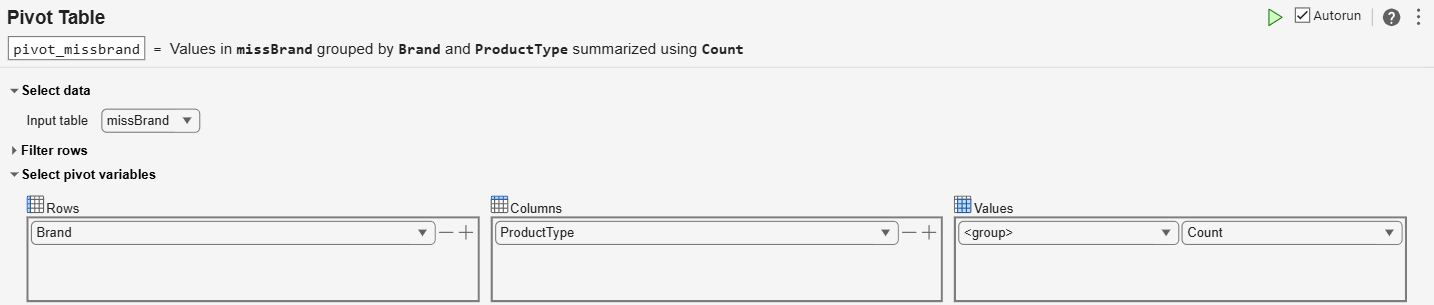

**Check the common Brand-ProductType by open "Compute by Group"**

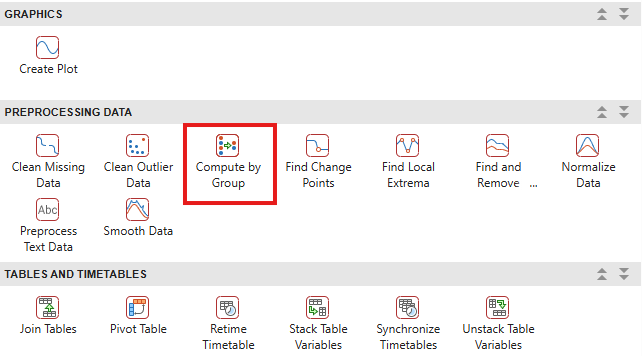

**Specify the variables **

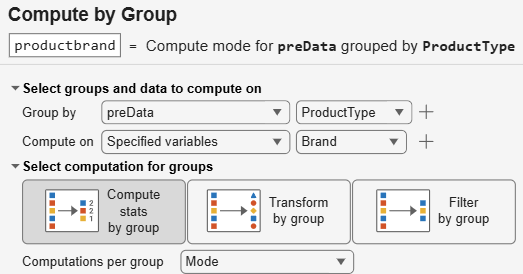

**Fill missing Brand with the common Brand of each ProductType**

First, check the product type of missing brand.

Then, find the index of the product type of missing brand that match the Brand-ProductType table.

Fill the missing brand with the common brand of each product type

Check the summary

#### 2.3.2: Fill missing UnitPrice

**Detect the missing UnitPrice and Diagnose**

**Check the data distribution to pick the right strategy**

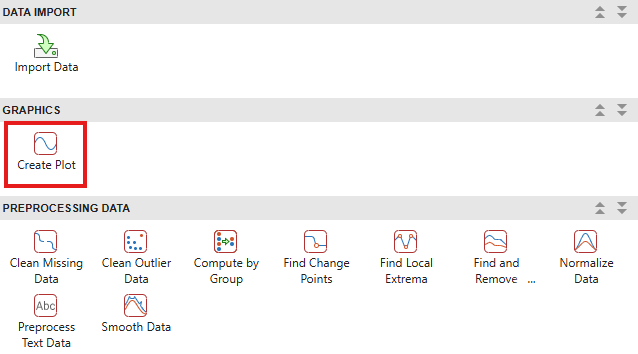

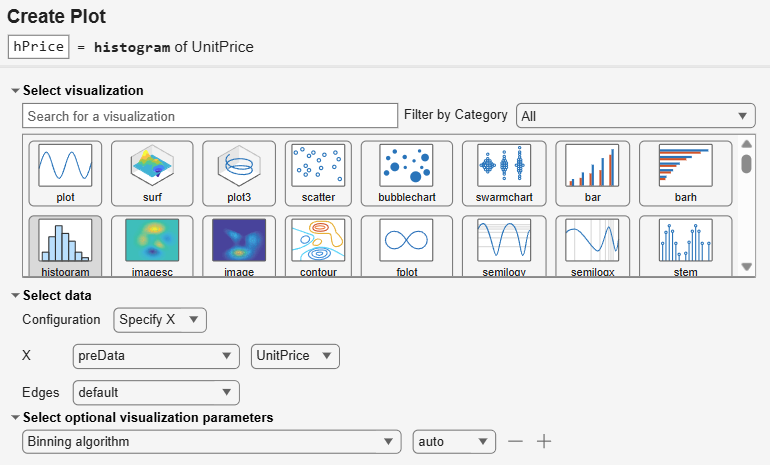

**Clean Outlier UnitPrice by select "Clean Outlier Data" task**

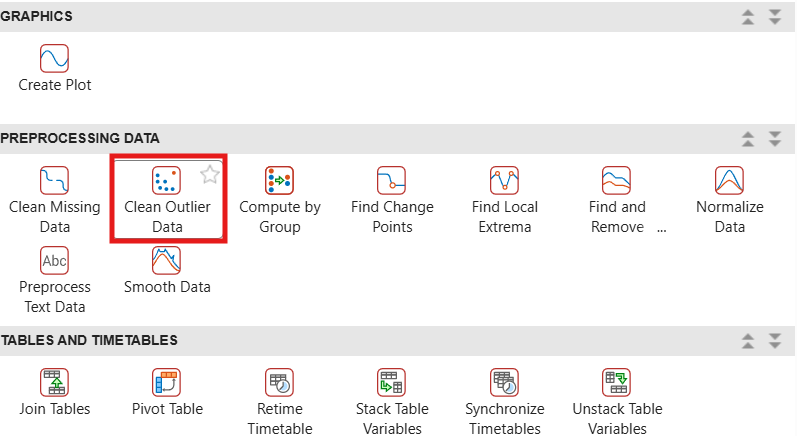

**Select the data and specify the option**

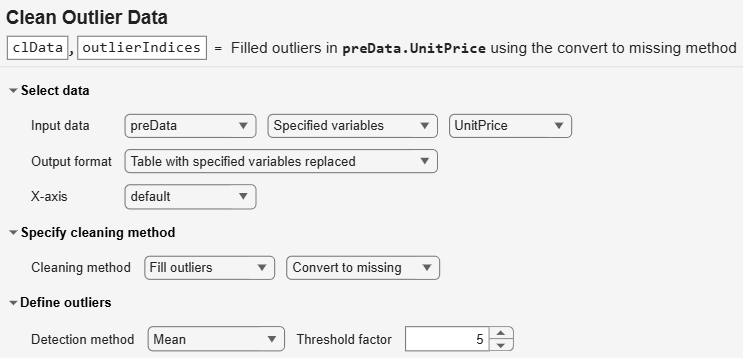

**Check UnitPrice distribution again**

**Replace missing UnitPrice values with the median cleaned price**

## Task 3: Business Exploratory Data Analysis (EDA)

**Goal**: understand the data before making decisions, and start exploring business relationships.

### 3.1: Where do the orders come from?

Hint: Histogram

### 3.2: Which product type sells most?

Hint: Histogram

### 3.3: What is the dominant product type of each brand?

Hint: Pivot Table

### 3.4: How does brand preference vary across countries?

Hint: Pivot Table

### 3.5: How does product type preference vary across countries?

Hint: Pivot Table

### 3.6: What is our revenue?

Hint: Compute by Group then Plot

### 3.7: How much our top spender spends?

Hint: Compute by Group, Sort rows, then Plot

Hint 2: